% Author: Wei Zhou
% Institution: Department of Mechanical and Materials Engineering, 
% University of Cincinnati, Cincinnati, OH 45221, USA
% Year: 2022
% Version: 2.0
% Reference: Empirical Fourier decomposition: An accurate signal decomposition method
% for nonlinear and non-stationary time series analysis
% https://doi.org/10.1016/j.ymssp.2021.108155
% =========================================================================

**Signal generation**

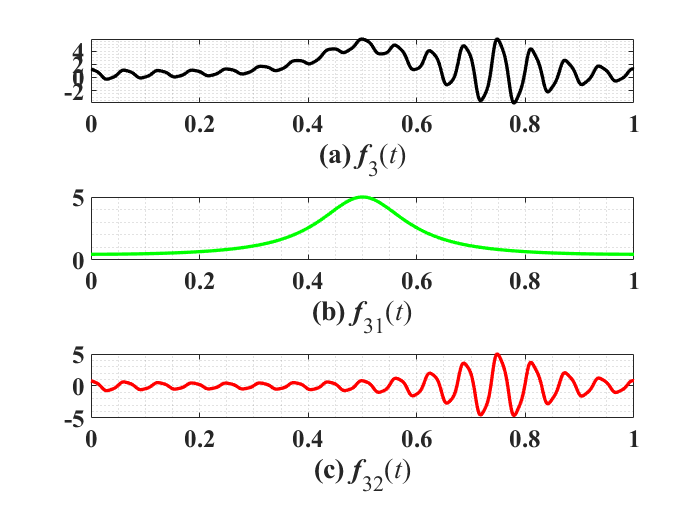

clear; clc; close all
set(0,'defaultlinelinewidth',2)
T = 1;          % total time
fs = 1000;      % sample frequency
t = (0:1/fs:T); % time step
f31 = 1./(1.2+cos(2*pi*t));
f12 = 2*cos(8*pi*t);
f32 = cos(32*pi*t+0.2*cos(64*pi*t))./(1.2+sin(2*pi*t));
sig3 = f31+f32;
% plot
figure
subplot(311)
plot(t,sig3,'k'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(a) \itf\rm_3(\itt\rm)')
subplot(312)
plot(t,f31,'g'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(b) \itf\rm_{31}(\itt\rm)')
subplot(313)
plot(t,f32,'r'); grid minor
set(gca,'XTick',(0:0.2:1))
xlabel('(c) \itf\rm_{32}(\itt\rm)')

**Using EFD to decompose**

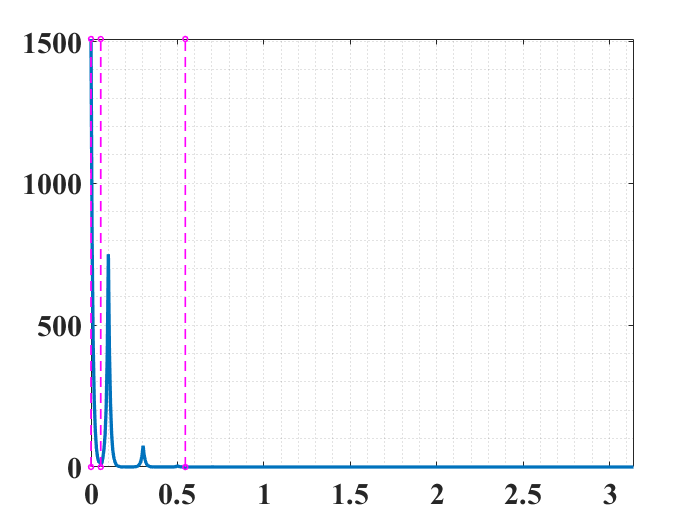

% the sig3 consists of 2 components, so 2 segments are needed
N = 2;
% perform EFD
[efd,cerf,boundaries] = EFD(sig3,N);
% plot the detected boundaries, to check the segmentation results
plotbounds(sig3,boundaries); grid minor

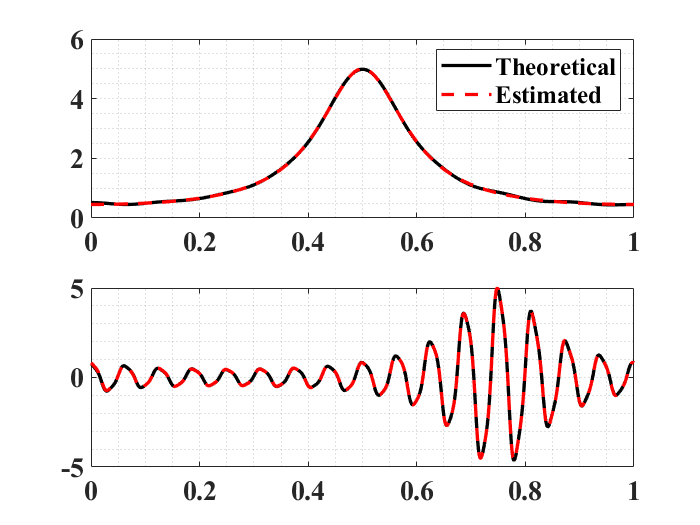

% two components
figure
subplot(211)
plot(t,efd{1,1},'k'); grid minor
hold on 
plot(t,f31,'--r')
set(gca,'XTick',(0:0.2:1))
legend('Theoretical','Estimated')
subplot(212)
plot(t,efd{2,1},'k'); grid minor
hold on 
plot(t,f32,'--r')
set(gca,'XTick',(0:0.2:1))

**TFR Results**

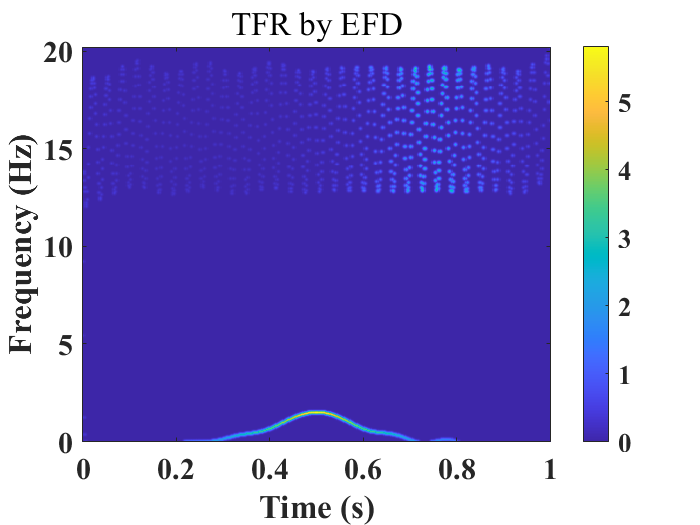

ff = [f31; f32];
for i = 1:N
    [inst_fre(i,:), inst_amp(i,:)] = IFIA(efd{i},fs);
    [inst_fre_ben(i,:), inst_amp_ben(i,:)] = IFIA(ff(i,:),fs);
end

[nt,tscale,fscale] = Plot_TFR(inst_fre(:,1:end)',inst_amp(:,1:end)',T); % magnitude value
q = fspecial('gaussian',7,0.6);
nsu = filter2(q,nt);
nsu = filter2(q,nsu);
figure; imagesc(tscale,fscale,nsu.^.5); colorbar; axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)'); title('TFR by EFD')

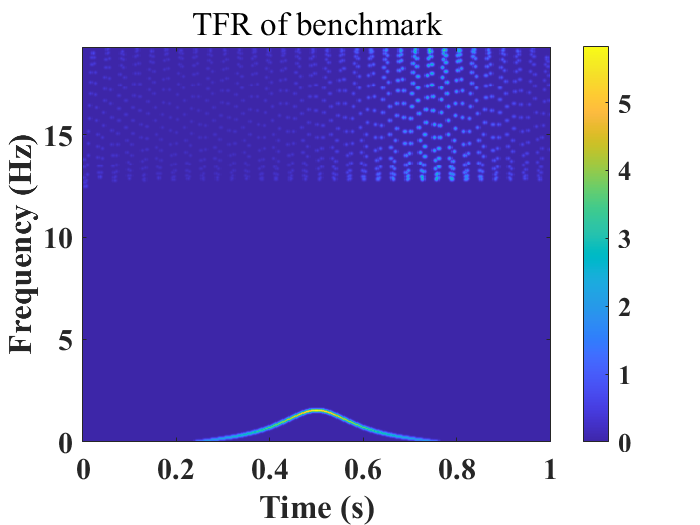


[nt,tscale,fscale] = Plot_TFR(inst_fre_ben(:,1:end)',inst_amp_ben(:,1:end)',T); % magnitude value
q = fspecial('gaussian',7,0.6);
nsu = filter2(q,nt);
nsu = filter2(q,nsu);
figure; imagesc(tscale,fscale,nsu.^.5); colorbar; axis xy
xlabel('Time (s)'); ylabel('Frequency (Hz)'); title('TFR of benchmark')